## Simulation variables

clear;
chan = "NoImpairments";
SNRdB = 40;
txsite = "false";
rxsite = "true";
txdevice = "pluto";
rxdevice = "pluto";
trigtime = false;
usrpTriggerTime = 3.8;
txGain = 0;
rxGain = 36;
Samplesize = 3; %2.3 and above works for pluto to pluto
maxChDelay = 2000;
brspace = 5;

% Input an image file and convert it to binary stream
fileTx = 'monkey.png';                   % Image file name
scale = 1;                    % Image scaling factor

## 5G  variables

[carrier, pdsch, NHARQProcesses, rvSeq, codeRate, encodeDLSCH, decodeDLSCH] = genvar5g;

## HARQ Management

harqEntity = HARQEntity(0:NHARQProcesses-1,rvSeq,pdsch.NumCodewords);

## Channel config

nTxAnts = 1;
nRxAnts = 1;

% Check that the number of layers is valid for the number of antennas
if pdsch.NumLayers > min(nTxAnts,nRxAnts)
    error("The number of layers ("+string(pdsch.NumLayers)+") must be smaller than min(nTxAnts,nRxAnts) ("+string(min(nTxAnts,nRxAnts))+")")
end

channel = nrTDLChannel;
channel.DelayProfile = "TDL-E";
channel.NumTransmitAntennas = nTxAnts;
channel.NumReceiveAntennas = nRxAnts;

ofdmInfo = nrOFDMInfo(carrier);
channel.SampleRate = ofdmInfo.SampleRate;

## Constellation plot setup

constPlot = comm.ConstellationDiagram;                                          % Constellation diagram object
constPlot.ReferenceConstellation = getConstellationRefPoints(pdsch.Modulation); % Reference constellation values
constPlot.EnableMeasurements = 1;                                               % Enable EVM measurements
constPlot.NumInputPorts = 10;


% Setup Spectrum viewer
spectrumScope = spectrumAnalyzer( ...
    SpectrumType='power-density', ...
    Title='Received Baseband 5G NR Signal Spectrum', ...
    YLabel='Power spectral density', ...
    Position=[69 376 800 450]);

## Variables

% Defining variable for storing data
rxBit = 0;
offset = 0;
longwave = 0.00001+0.00001i;

 
% Generate PDSCH indices info, which is needed to calculate the transport
% block size
[pdschIndices,pdschInfo] = nrPDSCHIndices(carrier,pdsch);

% Calculate transport block sizes
Xoh_PDSCH = 0;
trBlkSizes = nrTBS(pdsch.Modulation,pdsch.NumLayers,numel(pdsch.PRBSet),pdschInfo.NREPerPRB,codeRate,Xoh_PDSCH);
bitlen = trBlkSizes/8;

## Image to bit stream

% Setup handle for image plot
if ~exist('imFig','var') || ~ishandle(imFig) %#ok<SUSENS> 
    imFig = figure;
    imFig.NumberTitle = 'off';
    imFig.Name = 'Image Plot';
    imFig.Visible = 'off';
else
    clf(imFig); % Clear figure
    imFig.Visible = 'off';
end


fData = imread(fileTx);                          % Read image data from file
origSize = size(fData);                          % Original input image size
scaledSize = max(floor(scale.*origSize(1:2)),1); % Calculate new image size
heightIx = min(round(((1:scaledSize(1))-0.5)./scale+0.5),origSize(1));
widthIx = min(round(((1:scaledSize(2))-0.5)./scale+0.5),origSize(2));
fData = fData(heightIx,widthIx,:);               % Resize image
imsize = size(fData);                            % Store new image size
txImage = fData(:);
padZeros = bitlen-mod(length(txImage),bitlen);
txData = [txImage;zeros(padZeros,1)];
txDataBits1 = double(int2bit(txData,8,false));

trblkwithnum = trBlkSizes-32

trblkwithnum = 14312

slots = ceil(size(txDataBits1, 1)/(trblkwithnum));
frames = ceil(slots/10);

lengdata = size(txDataBits1,1);
lengframes = frames*(10*trBlkSizes-32);
missigbits = zeros((lengframes-lengdata), 1);
txDataBits = [txDataBits1; missigbits;];


% Plot transmit image
imFig.Visible = 'on';
subplot(211);
imshow(fData);
title('Transmitted Image');
subplot(212);
set(gca,'Visible','off');
set(findall(gca, 'type', 'text'), 'visible', 'on');

## SDR setup

 if strcmpi(txdevice,"usrp")
        % USRP transmit setup info
        tx = comm.SDRuTransmitter(...
               Platform = "B200", ...
              SerialNum = "3293CEA", ...
              CenterFrequency = 2400000000, ...
              InterpolationFactor = 256, ...
              MasterClockRate = 61.44e6, ...
              Gain = txGain);
        tx.EnableTimeTrigger = trigtime;
        tx.TriggerTime = usrpTriggerTime;
        BasebandSampleRate= channel.SampleRate;
    end
    
    if strcmpi(rxdevice,"usrp")
        % USRP rediever setup info
        rx = comm.SDRuReceiver(...
              Platform ="B200", ...
              SerialNum ="3293CEA", ...
              CenterFrequency =2400000000, ...
              DecimationFactor = 256, ...
              MasterClockRate = 61.44e6, ...
              OutputDataType = 'double' );
        rx.SamplesPerFrame =channel.SampleRate;
        rx.Gain = rxGain;
        rx.EnableBurstMode = false;
    end
       

    if strcmpi(txdevice,"pluto")
        % Pluto transmit setup info
        tx = sdrtx('Pluto', RadioID='usb:0');
        tx.CenterFrequency = 2400000000;
        tx.Gain = -txGain;
        tx.SamplesPerFrame = channel.SampleRate;
        tx.BasebandSampleRate = 61.44e6;
        tx.ShowAdvancedProperties = true;
        tx.FrequencyCorrection = 0;
    end

    if strcmpi(rxdevice,"pluto")
        % Pluto recieve setup info
        rx = sdrrx('Pluto', RadioID='usb:0');
        rx.CenterFrequency = 2400000000;
        rx.Gain = rxGain;
        rx.BasebandSampleRate = 61.44e6;
        rx.SamplesPerFrame = channel.SampleRate;
        rx.ShowAdvancedProperties = true;
        rx.FrequencyCorrection = 0;
        rx.OutputDataType = "double";  
    end


info(rx) 

## Establishing connection to hardware. This process can take several seconds.


ans = struct with fields:
    Status: 'No connection with device'


info(tx) 

## Establishing connection to hardware. This process can take several seconds.


ans = struct with fields:
    Status: 'No connection with device'


## Wave generation

frbeg = 1;
frend = (trBlkSizes*10)-32;
space = zeros((brspace*15360), 1);
for nframes = 0:frames-1
    data = txDataBits(frbeg:frend,1);
    frbeg = frbeg + trBlkSizes*10-trBlkSizes;
    frend = frend + trBlkSizes*10-trBlkSizes;
    framenum = int2bit(nframes,32);
    data = cat(1, data,framenum);
    [txWaveform, waveformInfo, trBlk, trBlkSizes] = TransmitterEntity3(harqEntity, data, nTxAnts, chan, channel, SNRdB, nRxAnts);
    longwave = cat(1, longwave,txWaveform, space);

    nframes
    if nframes == 0
            txBits = data;
            trstream = data;
    else
            txBits = cat(2,txBits,data);
            trstream = cat(1,trstream,data);
    end

 end

nframes = 0

nframes = 1

nframes = 2

nframes = 3

nframes = 4

nframes = 5

nframes = 6

nframes = 7

nframes = 8

nframes = 9

nframes = 10

nframes = 11

nframes = 12

## Wave transmison

if strcmpi(chan,"OverTheAir")
   tx(longwave);
else
   chInfo = info(channel);
   maxChDelay = 20000;%chInfo.MaximumChannelDelay;
   longwave = [zeros(maxChDelay,size(longwave,2));longwave; zeros(maxChDelay,size(longwave,2))];
end

## Wave capture

if strcmpi(chan,"OverTheAir")
   rxWaveform2 = capture(rx,4,'seconds');
else
   rxWaveform2 = longwave;
end
rxWaveform = rxWaveform2;

## Wave decoding

statusReport = 21×1 string array
    "Statusreport of frame"
    "0"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "1"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "2"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "3"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "4"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "5"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "6"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "7"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "8"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "9"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."


statusReport = 21×1 string array
    "Statusreport of frame"
    "0"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "1"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "2"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "3"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "4"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "5"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "6"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "7"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "8"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "9"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."


statusReport = 21×1 string array
    "Statusreport of frame"
    "0"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "1"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "2"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "3"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "4"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "5"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "6"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "7"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "8"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "9"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."


statusReport = 21×1 string array
    "Statusreport of frame"
    "0"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "1"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "2"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "3"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "4"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "5"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "6"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "7"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "8"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "9"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."


statusReport = 21×1 string array
    "Statusreport of frame"
    "0"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "1"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "2"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "3"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "4"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "5"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "6"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "7"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "8"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "9"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."


statusReport = 21×1 string array
    "Statusreport of frame"
    "0"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "1"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "2"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "3"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "4"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "5"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "6"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "7"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "8"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "9"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."


statusReport = 21×1 string array
    "Statusreport of frame"
    "0"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "1"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "2"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "3"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "4"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "5"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "6"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "7"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "8"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "9"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."


statusReport = 21×1 string array
    "Statusreport of frame"
    "0"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "1"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "2"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "3"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "4"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "5"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "6"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "7"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "8"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "9"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."


statusReport = 21×1 string array
    "Statusreport of frame"
    "0"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "1"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "2"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "3"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "4"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "5"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "6"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "7"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "8"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "9"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."


statusReport = 21×1 string array
    "Statusreport of frame"
    "0"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "1"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "2"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "3"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "4"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "5"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "6"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "7"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "8"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "9"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."


statusReport = 21×1 string array
    "Statusreport of frame"
    "0"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "1"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "2"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "3"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "4"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "5"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "6"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "7"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "8"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "9"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."


statusReport = 21×1 string array
    "Statusreport of frame"
    "0"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "1"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "2"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "3"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "4"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "5"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "6"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "7"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "8"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "9"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."


statusReport = 21×1 string array
    "Statusreport of frame"
    "0"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "1"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "2"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "3"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "4"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "5"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "6"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "7"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "8"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."
    "9"
    "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."


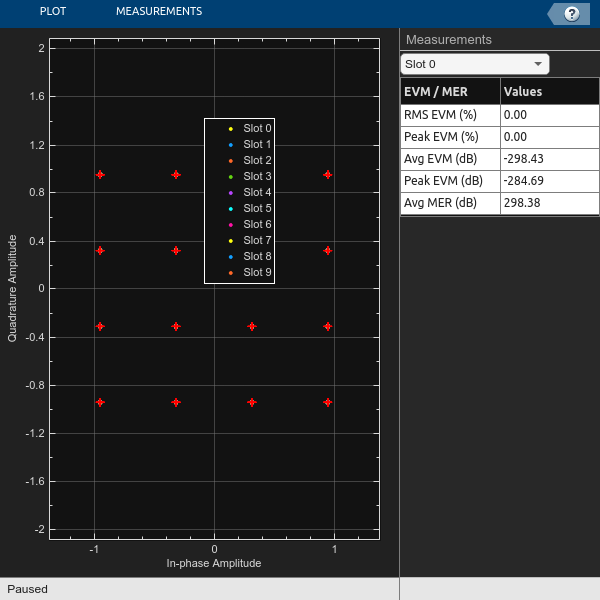

stframe = 1;
wavelength = size(rxWaveform,1); 
enframe = 15500*11;
if enframe >= (wavelength - stframe)
   enframe = wavelength;
end



for nframes = 0:frames-1
    
    dmrsSymbols = nrPDSCHDMRS(carrier,pdsch);
    dmrsIndices = nrPDSCHDMRSIndices(carrier,pdsch);
    [pdschIndices,pdschInfo] = nrPDSCHIndices(carrier,pdsch);

    %% Timing Synchronization
    [t,mag] = nrTimingEstimate(carrier,rxWaveform,dmrsIndices,dmrsSymbols);
    offset = hSkipWeakTimingOffset(offset,t,mag);

    pakoff = 10*15360;

    frawave = rxWaveform(1+offset:1+offset+pakoff,:);
    rxWaveform(1+offset:1+offset+pakoff,:) = zeros;

    
    % Frames decoding
    [decbits, statusReport, pdschEq] = RecieverEntity3(harqEntity, frawave, 0, channel);
    decbits;
    statusReport

   
    constPlot.ChannelNames = "Slot "+(0:1:9);
    constPlot.ShowLegend = true;
    % Constellation for the first layer has a higher SNR than that for the
    % last layer. Flip the layers so that the constellations do not mask
    % each other.
    constPlot(fliplr(pdschEq(1:7488, 1)), ...
              fliplr(pdschEq(1:7488, 2)), ...
              fliplr(pdschEq(1:7488, 3)), ...
              fliplr(pdschEq(1:7488, 4)), ...
              fliplr(pdschEq(1:7488, 5)), ...
              fliplr(pdschEq(1:7488, 6)), ...
              fliplr(pdschEq(1:7488, 7)), ...
              fliplr(pdschEq(1:7488, 8)), ...
              fliplr(pdschEq(1:7488, 9)), ...
              fliplr(pdschEq(1:7488, 10)));
    
   


    if nframes == 0
            rxBits = decbits;
    else
            rxBits = cat(2,rxBits,decbits);
    end
    
end

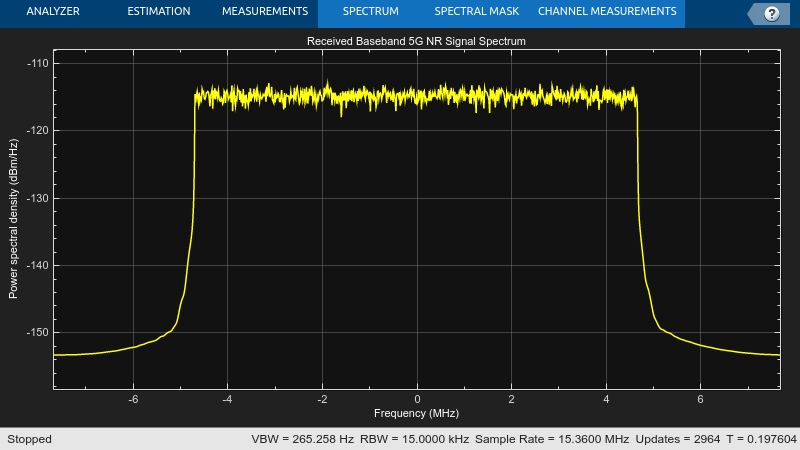



spectrumScope.SampleRate = channel.SampleRate;
spectrumScope(rxWaveform2);
release(spectrumScope);

## SDR release

release(tx);
fprintf('Recieving stopped.\n')

Recieving stopped.


release(rx);
fprintf('Transmission stopped.\n')

Transmission stopped.


## Converting to string array

numsort = 0;
frame = 1;
sort = 0;




while sort == 0

 if frame == size(rxBits, 2)
     frame = 1;
 else
    frame = frame +1;
 end

 frsize = trBlkSizes*10;
 nfrsize = frsize - 31;
 numf = bit2int(rxBits(nfrsize:frsize, frame), 32);

 if numf == numsort
     numsort = numsort + 1;
     numf

    
     if rxBits(1:end,frame) == txBits(1:end,numsort)
        status = "succes"
     else
        status = "fail"
     end
     
     if numf == 0
        imgbits = rxBits(1:end-32, frame);
     else
        imgbits = cat(1,imgbits ,rxBits(1:end-32, frame));
     end
       
     if numsort == size(rxBits, 2)
         sort = 1;
     end

 end
end

numf = int64
0

status = "succes"

numf = int64
1

status = "succes"

numf = int64
2

status = "succes"

numf = int64
3

status = "succes"

numf = int64
4

status = "succes"

numf = int64
5

status = "succes"

numf = int64
6

status = "succes"

numf = int64
7

status = "succes"

numf = int64
8

status = "succes"

numf = int64
9

status = "succes"

numf = int64
10

status = "succes"

numf = int64
11

status = "succes"

numf = int64
12

status = "succes"

## Removing empty slots


dataslots = size(missigbits, 1);

imgbits(end-dataslots+1:end) = [];



 % Reshape such that each column length has bits equal to the
 % transportblock 
 rxData = reshape(imgbits,8,[]);

 decData = bit2int(reshape(rxData(:),8,[]),8,false)';

 % Append NaNs to fill any missing image data
 if length(decData)<length(txImage)
    numMissingData = length(txImage)-length(decData);
    decData = [decData;NaN(numMissingData,1)];
 else
    decData = decData(1:length(txImage));
 end

 % Recreate image from received data
 fprintf('\nConstructing image from received data.\n');


Constructing image from received data.


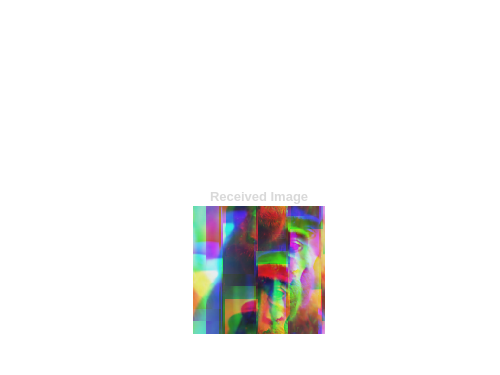

 receivedImage = uint8(reshape(decData,imsize));
 % Plot received image
 if exist('imFig','var') && ishandle(imFig) % If Tx figure is open
    figure(imFig); subplot(212);
 else
    figure; subplot(212);
 end
 imshow(receivedImage);
 title(sprintf('Received Image'));

## Local Functions

function noise = generateAWGN(SNRdB,nRxAnts,Nfft,sizeRxWaveform)
% Generate AWGN for a given value of SNR in dB (SNRDB), which is the
% receiver SNR per RE and antenna, assuming the channel does
% not affect the power of the signal. NRXANTS is the number of receive
% antennas. NFFT is the FFT size used in OFDM demodulation. SIZERXWAVEFORM
% is the size of the receive waveform used to calculate the size of the
% noise matrix.

    % Normalize noise power by the IFFT size used in OFDM modulation, as
    % the OFDM modulator applies this normalization to the transmitted
    % waveform. Also normalize by the number of receive antennas, as the
    % channel model applies this normalization to the received waveform by
    % default. The SNR is defined per RE for each receive antenna (TS
    % 38.101-4).
    SNR = 10^(SNRdB/10); % Calculate linear noise gain
    N0 = 1/sqrt(2.0*nRxAnts*double(Nfft)*SNR);
    noise = N0*complex(randn(sizeRxWaveform),randn(sizeRxWaveform));
end

function wtx = getPrecodingMatrix(PRBSet,NLayers,hestGrid)
% Calculate precoding matrix given an allocation and a channel estimate
    
    % Allocated subcarrier indices
    allocSc = (1:12)' + 12*PRBSet(:).';
    allocSc = allocSc(:);
    
    % Average channel estimate
    [~,~,R,P] = size(hestGrid);
    estAllocGrid = hestGrid(allocSc,:,:,:);
    Hest = permute(mean(reshape(estAllocGrid,[],R,P)),[2 3 1]);
    
    % SVD decomposition
    [~,~,V] = svd(Hest);
    
    wtx = V(:,1:NLayers).';
    wtx = wtx/sqrt(NLayers); % Normalize by NLayers
end

function estChannelGrid = getInitialChannelEstimate(channel,carrier)
% Obtain an initial channel estimate for calculating the precoding matrix.
% This function assumes a perfect channel estimate

    % Clone of the channel
    chClone = channel.clone();
    chClone.release();

    % No filtering needed to get channel path gains
    chClone.ChannelFiltering = false;    
    
    % Get channel path gains
    [pathGains,sampleTimes] = chClone();
    
    % Perfect timing synchronization
    pathFilters = getPathFilters(chClone);
    offset = nrPerfectTimingEstimate(pathGains,pathFilters);
    
    % Perfect channel estimate
    estChannelGrid = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,offset,sampleTimes);
end

function refPoints = getConstellationRefPoints(mod)
% Calculate the reference constellation points for a given modulation
% scheme.
    switch mod
        case "QPSK"
            nPts = 4;
        case "16QAM"
            nPts = 16;
        case "64QAM"
            nPts = 64;
        case "256QAM"
            nPts = 256;            
    end
    binaryValues = int2bit(0:nPts-1,log2(nPts));
    refPoints = nrSymbolModulate(binaryValues(:),mod);
end

function estChannelGrid = precodeChannelEstimate(estChannelGrid,W)
% Apply precoding matrix W to the last dimension of the channel estimate.

    % Linearize 4-D matrix and reshape after multiplication
    K = size(estChannelGrid,1);
    L = size(estChannelGrid,2);
    R = size(estChannelGrid,3);
    estChannelGrid = reshape(estChannelGrid,K*L*R,[]);
    estChannelGrid = estChannelGrid*W;
    estChannelGrid = reshape(estChannelGrid,K,L,R,[]);

end

